%% Initialization
clear ; close all; clc

fprintf('\nRunning K-Means clustering on pixels from an image.\n\n');


Running K-Means clustering on pixels from an image.



%  Load an image 
A = double(imread('20250216_180310-small.jpg'));

A = A / 255; % Divide by 255 so that all values are in the range 0 - 1

% Size of the image
img_size = size(A);

% Reshape the image into an Nx3 matrix where N = number of pixels.
% Each row will contain the Red, Green and Blue pixel values
% This gives us our dataset matrix X that we will use K-Means on.
X = reshape(A, img_size(1) * img_size(2), 3);

% Run your K-Means algorithm on this data
K = 16; 
max_iters = 10;

% When using K-Means, it is important the initialize the centroids
% randomly. 
initial_centroids = kMeansInitCentroids(X, K);

% Run K-Means
[centroids, idx] = runkMeans(X, initial_centroids, max_iters);

K-Means iteration 1/10...
K-Means iteration 2/10...
K-Means iteration 3/10...
K-Means iteration 4/10...
K-Means iteration 5/10...
K-Means iteration 6/10...
K-Means iteration 7/10...
K-Means iteration 8/10...
K-Means iteration 9/10...
K-Means iteration 10/10...



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

fprintf('\nApplying K-Means to compress an image.\n\n');


Applying K-Means to compress an image.



% Find closest cluster members
idx = findClosestCentroids(X, centroids);

% Essentially, now we have represented the image X as in terms of the
% indices in idx. 
% We can now recover the image from the indices (idx) by mapping each pixel
% (specified by its index in idx) to the centroid value
X_recovered = centroids(idx,:);

% Reshape the recovered image into proper dimensions
X_recovered = reshape(X_recovered, img_size(1), img_size(2), 3);

% Display the original image 
subplot(1, 2, 1);
imagesc(A); 
title('Original');

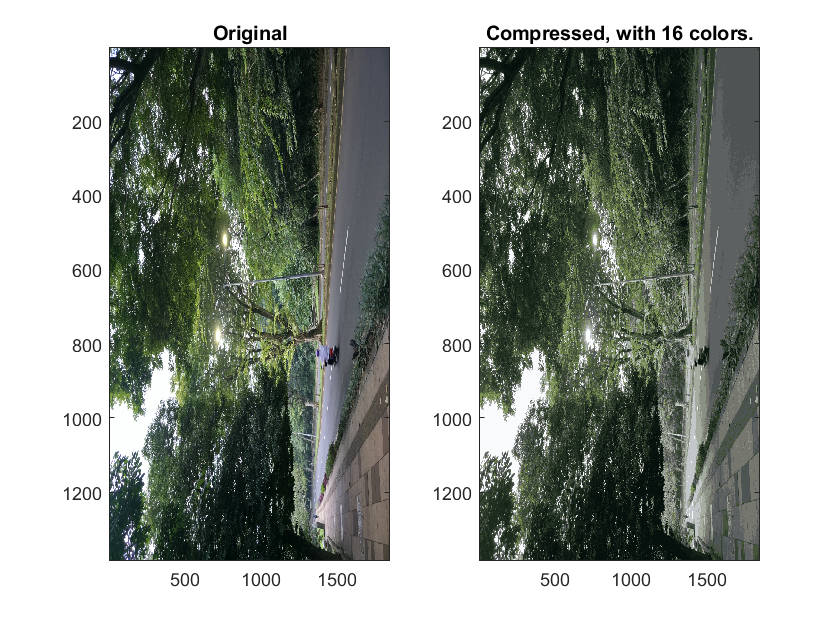

% Display compressed image side by side
subplot(1, 2, 2);
imagesc(X_recovered)
title(sprintf('Compressed, with %d colors.', K));

% Save the compressed image
output_filename = '20250216_180310_compressed.jpg';  % Modify this as per your original filename
imwrite(X_recovered, output_filename);
fprintf('Compressed image saved as %s\n', output_filename);

Compressed image saved as 20250216_180310_compressed.jpg
